clear all
load TR4_data.mat
syms t
syms q1(t) q2(t) q3(t)
syms Q1 Q2 Q3 Q1p Q2p Q3p
Q(1)=q1;
Q(2)=q2;
Q(3)=q3;
L=sym("l",[1 4]);
J=TR4_jacobian(Q,L);
Jp=diff(J,t)
Jp=subs(Jp,diff(q2),Q2p);
Jp=subs(Jp,diff(q1),Q1p);
Jp=subs(Jp,diff(q3),Q3p);
Jp=subs(Jp,q1,Q1);
Jp=subs(Jp,q2,Q2);
Jp=subs(Jp,q3,Q3)
Jp=matlabFunction(Jp)
detJ=det(J);
assume(Q,'positive')
detj=simplify(detJ)
latex(detJ)
detJ=matlabFunction(detJ);
J=matlabFunction(J)

## calcolo Jacobiano (vedere file .mlx per commenti)

clear all
Q=sym("q",[1 3])
L=sym("l",[1 4])
load TR4_data.mat
[M01_ M1_1 M12 M23]=TR4_positionMat(Q,L);
M01=M01_*M1_1;
M02=M01*M12;
M03=M02*M23;
S=M03*[0 0 0 1]'
S=S(1:3)
J=jacobian(S,Q)
detJ=det(J);

J=matlabFunction(J)

## Calcolo Jacobiano punto (vedere file .mlx per commenti)

clear all
load TR4_data.mat
syms t
syms q1(t) q2(t) q3(t)
syms Q1 Q2 Q3 Q1p Q2p Q3p
Q(1)=q1;
Q(2)=q2;
Q(3)=q3;
L=sym("l",[1 4]);
J=TR4_jacobian(Q,L);
Jp=diff(J,t)
Jp=subs(Jp,diff(q2),Q2p);
Jp=subs(Jp,diff(q1),Q1p);
Jp=subs(Jp,diff(q3),Q3p);
Jp=subs(Jp,q1,Q1);
Jp=subs(Jp,q2,Q2);
Jp=subs(Jp,q3,Q3)
Jp=matlabFunction(Jp)

## disegno determinante jacobiano

clear all
close all
load TR4_data.mat

L=link;
Q=sym("q",[1 3]);
detJ=detJacobian(Q,link)

$$detJ = -\frac{\cos\left(q_{1}\right)\,\sin\left(q_{3}\right)\,{\cos\left(q_{2}\right)}^{2}\,\cos\left(q_{3}\right)}{31250}-\frac{5329390911803167\,\cos\left(q_{1}\right)\,\sin\left(q_{3}\right)\,{\cos\left(q_{2}\right)}^{2}}{295147905179352825856}+\frac{\sin\left(q_{1}\right)\,\cos\left(q_{2}\right)\,{\cos\left(q_{3}\right)}^{2}}{31250}+\frac{5329390911803167\,\sin\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)}{295147905179352825856}-\frac{\cos\left(q_{1}\right)\,\sin\left(q_{3}\right)\,\cos\left(q_{3}\right)\,{\sin\left(q_{2}\right)}^{2}}{31250}-\frac{5329390911803167\,\cos\left(q_{1}\right)\,\sin\left(q_{3}\right)\,{\sin\left(q_{2}\right)}^{2}}{295147905179352825856}$$

eqn=simplify(detJ)

$$eqn = -\frac{\left(\cos\left(q_{1}\right)\,\sin\left(q_{3}\right)-\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\right)\,\left(147573952589676412928\,\cos\left(q_{3}\right)+83271732996924484375\right)}{4611686018427387904000000}$$


%due termini del deteminante per vedere quando =0
e1=(cos(Q(1))*sin(Q(3)) - cos(Q(2))*cos(Q(3))*sin(Q(1)))==0;
e2=(14.7*cos(Q(3)) + 8.3)==0; 
%risolvo rispetto a Q3
e2=solve(e2,Q(3))

$$e2 = \left(\begin{array}{c} \pi +\mathrm{acos}\left(\frac{83}{147}\right)\\ \pi -\mathrm{acos}\left(\frac{83}{147}\right) \end{array}\right)$$


eqn=solve(eqn,Q(3))

$$eqn = \begin{array}{l} \left(\begin{array}{c} -\log\left(\sigma_{1}\right)\,\mathrm{i}\\ -\log\left(-\sigma_{1}\right)\,\mathrm{i}\\ \pi +\mathrm{acos}\left(\frac{83271732996924484375}{147573952589676412928}\right)\\ \pi -\mathrm{acos}\left(\frac{83271732996924484375}{147573952589676412928}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{2\,{\mathrm{e}}^{2\,q_{1}\,\mathrm{i}}+2\,{\mathrm{e}}^{2\,q_{2}\,\mathrm{i}}-{\mathrm{e}}^{4\,q_{1}\,\mathrm{i}}-{\mathrm{e}}^{4\,q_{2}\,\mathrm{i}}+12\,{\mathrm{e}}^{2\,q_{1}\,\mathrm{i}}\,{\mathrm{e}}^{2\,q_{2}\,\mathrm{i}}+2\,{\mathrm{e}}^{2\,q_{1}\,\mathrm{i}}\,{\mathrm{e}}^{4\,q_{2}\,\mathrm{i}}+2\,{\mathrm{e}}^{2\,q_{2}\,\mathrm{i}}\,{\mathrm{e}}^{4\,q_{1}\,\mathrm{i}}-{\mathrm{e}}^{4\,q_{1}\,\mathrm{i}}\,{\mathrm{e}}^{4\,q_{2}\,\mathrm{i}}-1}}{1+2\,{\mathrm{e}}^{q_{2}\,\mathrm{i}}+{\mathrm{e}}^{2\,q_{2}\,\mathrm{i}}+2\,{\mathrm{e}}^{2\,q_{1}\,\mathrm{i}}\,{\mathrm{e}}^{q_{2}\,\mathrm{i}}-{\mathrm{e}}^{2\,q_{1}\,\mathrm{i}}\,{\mathrm{e}}^{2\,q_{2}\,\mathrm{i}}-{\mathrm{e}}^{2\,q_{1}\,\mathrm{i}}} \end{array}$$

eqn=matlabFunction(eqn)

eqn = function_handle with value:
    @(q1,q2)[log(sqrt(exp(q1.*2.0i).*2.0+exp(q2.*2.0i).*2.0-exp(q1.*4.0i)-exp(q2.*4.0i)+exp(q1.*2.0i).*exp(q2.*2.0i).*1.2e+1+exp(q1.*2.0i).*exp(q2.*4.0i).*2.0+exp(q2.*2.0i).*exp(q1.*4.0i).*2.0-exp(q1.*4.0i).*exp(q2.*4.0i)-1.0)./(-exp(q1.*2.0i)+exp(q2.*1i).*2.0+exp(q2.*2.0i)+exp(q1.*2.0i).*exp(q2.*1i).*2.0-exp(q1.*2.0i).*exp(q2.*2.0i)+1.0)).*-1i;log(-sqrt(exp(q1.*2.0i).*2.0+exp(q2.*2.0i).*2.0-exp(q1.*4.0i)-exp(q2.*4.0i)+exp(q1.*2.0i).*exp(q2.*2.0i).*1.2e+1+exp(q1.*2.0i).*exp(q2.*4.0i).*2.0+exp(q2.*2.0i).*exp(q1.*4.0i).*2.0-exp(q1.*4.0i).*exp(q2.*4.0i)-1.0)./(-exp(q1.*2.0i)+exp(q2.*1i).*2.0+exp(q2.*2.0i)+exp(q1.*2.0i).*exp(q2.*1i).*2.0-exp(q1.*2.0i).*exp(q2.*2.0i)+1.0)).*-1i;pi+acos(5.642712113868649e-1);pi-acos(5.642712113868649e-1)]

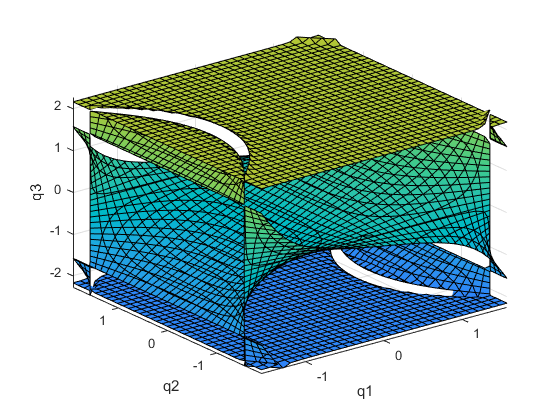

fimplicit3(detJ)
xlim([-Con(1,1)/2 Con(1,1)/2])
ylim([-Con(1,2)/2 Con(1,2)/2])
zlim([-Con(1,3)/2 Con(1,3)/2])
xlabel("q1")
ylabel("q2")
zlabel("q3")

## prova -> plot di alcune singolarità e dei punti

close all
a=100;
b=100;
i=0;
realSol=NaN(3,a*b*4);
for q1 = linspace(-Con(1,1)/2,Con(1,1)/2,a)
    for q2 = linspace(-Con(1,2)/2,Con(1,2)/2,b)
        q3=eqn(q1,q2);
        for q=q3'
            if isreal(q)
                i=i+1;
                realSol(:,i)=[q1;q2;q];
            end
        end
        
    end
end

Unrecognized function or variable 'Con'.

for i=1:a*b*4
    if(isnan(realSol(1,i)))
        length=i-1;
        break
    end
end
realSol=realSol(:,1:length);
plot3(realSol(1,:),realSol(2,:),realSol(3,:),'.')
S=zeros(4,length);
for i=1:length
    S(:,i)=TR4_dirKin(realSol(:,i),link);
end
% for i=1:length
%     TR4_plot_c(link,realSol(:,i),25+i,offset,0);
%     xlabel("X")
%     ylabel("Y")
%     zlabel("Z")
%     view([45 45])
%     axis equal
% end

## eseguo una discretizzazione del work space per eseguire uno slice del workspace

## discretization pt1

div=150;
Xdiv=div;Ydiv=div;Zdiv=div;
xmax=max(S(1,:));
xmin=min(S(1,:));
ymax=max(S(2,:));
ymin=min(S(2,:));
zmax=max(S(3,:));
zmin=min(S(3,:));
X=linspace(xmin,xmax,Xdiv);
dx=X(2)-X(1);
Y=linspace(ymin,ymax,Ydiv);
dy=Y(2)-Y(1);
Z=linspace(zmin,zmax,Zdiv);
dz=Z(2)-Z(1);

## discretization pt2

space=zeros(Xdiv,Ydiv,Zdiv);
for p=S
    x=p(1);
    y=p(2);
    z=p(3);
    xinf=find(X<=x);
    xinf=xinf(end);
    yinf=find(Y<=y);
    yinf=yinf(end);
    zinf=find(Z<=z);
    zinf=zinf(end);
    space(xinf,yinf,zinf)=1;
end

## plot results of workspace and singolarità

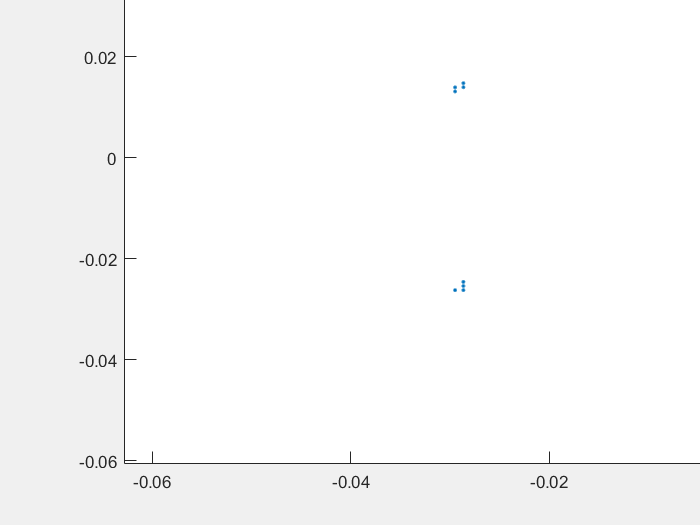

close all
clear all
load Singolarità_Cartesiane.mat
load TR4_data.mat
sliderX(space,Xdiv,X,Y,Z)

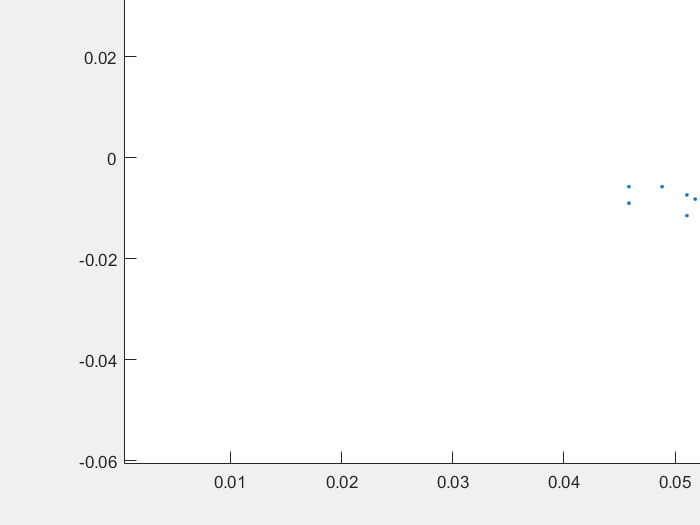

sliderY(space,Ydiv,X,Y,Z)

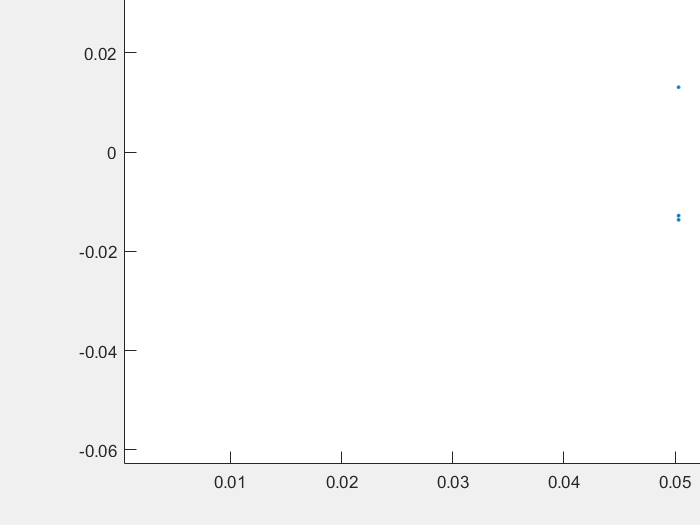

sliderZ(space,Zdiv,X,Y,Z)

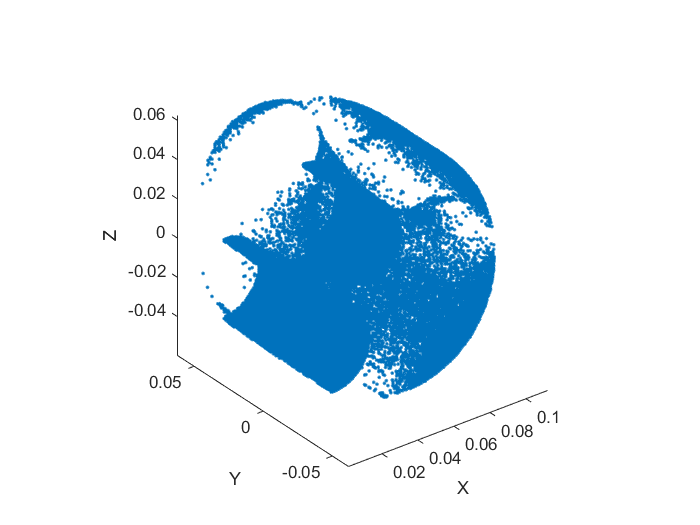

point2plot=nan(3,Xdiv*Ydiv*Zdiv);
point2plot_inner=nan(3,Xdiv*Ydiv*Zdiv);
p=1;
for i = 1:Xdiv
    for j = 1:Ydiv
        for k = 1:Zdiv
            if(space(i,j,k)==1)
                point2plot(:,p)=[X(i) Y(j) Z(k)]';
                p=p+1;
            end
        end
    end
end
figure
plot3(point2plot(1,:),point2plot(2,:),point2plot(3,:),'.')
axis equal
% hold on
% load TR4_ws_dv_constrain.mat
% point2plot=nan(3,Xdiv*Ydiv*Zdiv);
% point2plot_inner=nan(3,Xdiv*Ydiv*Zdiv);
% p=1;
% for i = 1:Xdiv
%     for j = 1:Ydiv
%         for k = 1:Zdiv
%             if(space_(i,j,k)==1)
%                 point2plot(:,p)=[X(i) Y(j) Z(k)]';
%                 p=p+1;
%             end
%         end
%     end
% end
% plot3(point2plot(1,:),point2plot(2,:),point2plot(3,:),'.')
% axis equal
xlabel('X')
ylabel('Y')
zlabel('Z')

% legend('singolarità','workspace')
figure
for i=1:10
    index(i)=floor(rand()*p);
%     TR4_plot_c(link,)
end

index = 34750

index =        34750       38634


index =        34750       38634        5416


index =        34750       38634        5416       38958


index =        34750       38634        5416       38958       26972


index =        34750       38634        5416       38958       26972        4160


index =        34750       38634        5416       38958       26972        4160       11878


index =        34750       38634        5416       38958       26972        4160       11878       23326


index =        34750       38634        5416       38958       26972        4160       11878       23326       40840


index =        34750       38634        5416       38958       26972        4160       11878       23326       40840       41155


## save

%save Singolarità_Cartesiane S space X Xdiv Y Ydiv Z Zdiv